# CAA_ESERCITAZIONE_ESAME_27042026

clear; close all; clc;

## Definizioni 

#### Variabili Simboliche 

syms x1 x2 theta dx1 dx2 dtheta ddx1 ddx2 ddtheta u1 u2 real

#### Parametri

m1 = 1.5;
m2 = 1.0;
mp = 0.25;
l = 0.40;
J = 0.013;
k = 35;
b = 4;
g = 9.81;

#### Ingresso-Stato-Uscita

u = [u1;
     u2];

x = [x1;
     x2;
     theta;
     dx1;
     dx2;
     dtheta];

y = [x1;
     x2;
     theta];

n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico Non Lineare

eq1 = (m1+mp)*ddx1 + mp*l*cos(theta)*ddtheta - mp*l*sin(theta)*dtheta^2 + k*(x1-x2) + b*(dx1-dx2) == u1;
eq2 = m2*ddx2 + k*(x2-x1) +b*(dx2-dx1) == u2;
eq3 = (J+mp*l^2)*ddtheta + mp*l*cos(theta)*ddx1 - mp*g*l*sin(theta) == 0;

eqs = [eq1;
       eq2;
       eq3];

dd = solve(eqs, [ddx1, ddx2, ddtheta], "ReturnConditions",true);

f = [dx1;
     dx2;
     dtheta;
     dd.ddx1;
     dd.ddx2;
     dd.ddtheta];

g = y;

## Punti di Equilibrio e Linearizzazione

#### Punti di Equilibrio

ddx1_sym = dd.ddx1;
ddx2_sym = dd.ddx2;
ddtheta_sym = dd.ddtheta;

eq_ddx1 = subs(ddx1_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;
eq_ddx2 = subs(ddx2_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;
eq_ddtheta = subs(ddtheta_sym, {dx1, dx2, dtheta, u1, u2}, {0, 0, 0, 0, 0}) == 0;

peql = solve([eq_ddx1, eq_ddx2, eq_ddtheta, x1==0], [x1, x2, theta], "ReturnConditions", true);

x_star = [peql.x1;
          peql.x2;
          peql.theta;
          0;
          0;
          0]

$$x\_star = \left(\begin{array}{c} 0\\ 0\\ \pi \,k\\ 0\\ 0\\ 0 \end{array}\right)$$

#### Linearizzazione attorno a (x_bar, u_bar)

x_bar = zeros(6,1);
u_bar = zeros(2,1);

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_bar; u_bar]));
B = double(subs(B_sym, [x; u], [x_bar; u_bar]));
C = double(subs(C_sym, [x; u], [x_bar; u_bar]));
D = double(subs(D_sym, [x; u], [x_bar; u_bar]));

sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4  -22.42   22.42  -1.185  -2.562   2.562       0
   x5      35     -35       0       4      -4       0
   x6    42.3   -42.3   20.75   4.834  -4.834       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  0.6405       0
   x5       0       1
   x6  -1.208       0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


#### Verifica Controllabilità e Osservabilità

Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## Controllo LQR con Azione Integrale 

#### Specifiche 

r = [0.15;
     0.20];

Ts = 5;

#### Sistema Aumentato

C_LQR = [1, zeros(1,n-1);
         0, 1, zeros(1,n-2)];

% Numero di uscite da retroazionare
p_tilde = size(C_LQR, 1);

% Dimensione dello stato aumentato
n_tilde = n + p_tilde;

A_tilde = [A, zeros(n,p_tilde);
           -C_LQR, zeros(p_tilde)];

% Shift di A_tilde per rispettae la specifica su Ts
alpha = 4/Ts;
A_hat = A_tilde + alpha*eye(n_tilde);

B_tilde = [B;
           zeros(2)];

C_tilde = [eye(n), zeros(n,p_tilde)];

D_tilde = zeros(n, m);

sys_aum = ss(A_hat, B_tilde, C_tilde, D_tilde)


sys_aum =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1     0.8       0       0       1       0       0       0       0
   x2       0     0.8       0       0       1       0       0       0
   x3       0       0     0.8       0       0       1       0       0
   x4  -22.42   22.42  -1.185  -1.762   2.562       0       0       0
   x5      35     -35       0       4    -3.2       0       0       0
   x6    42.3   -42.3   20.75   4.834  -4.834     0.8       0       0
   x7      -1       0       0       0       0       0     0.8       0
   x8       0      -1       0       0       0       0       0     0.8
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  0.6405       0
   x5       0       1
   x6  -1.208       0
   x7       0       0
   x8       0       0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   1   0   0   0   0   0   0
   y3   0   0   1   

#### Sintesi LQR

Q_bar = 1;
Q = C_tilde'*Q_bar*C_tilde + blkdiag(zeros(n), 100*eye(p_tilde))

Q =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0   100     0
     0     0     0     0     0     0     0   100



R = eye(m)

R =      1     0
     0     1



[K_LQR, ~, ~] = lqr(sys_aum, Q, R);

K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

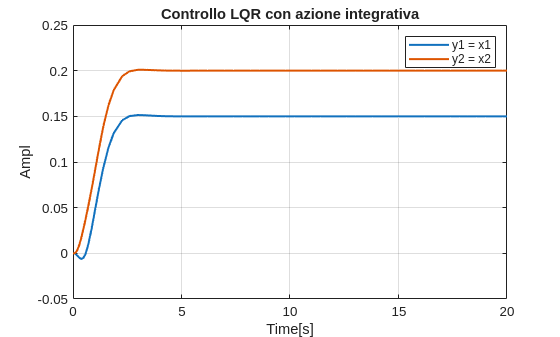

% Plot MATLAB
out = sim('Verifica_LQR_27042026.slx');
y1 = out.y1.Data;
y2 = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1, "LineWidth", 1.5);
grid on
hold on
plot(time, y2, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x2');
title('Controllo LQR con azione integrativa');